clear
load partI.mat
whos

  Name        Size                 Bytes  Class      Attributes

  S         115x90x64            5299200  double               
  S0        115x90                 82800  double               
  b           1x1                      8  double               
  g          64x3                   1536  double               
  mask      115x90                 10350  logical              



% imshow(mask, 'initialmagnification', 'fit')
% [X,Y,num_dirs] = size(S)
% assert(isequal(size(g), [num_dirs 3]))

% cleaning the data
S

S = S(:,:,1) =

   1.0e+03 *

    0.0104    0.0077    0.0072    0.0075    0.0049    0.0046    0.0142    0.0067    0.0098    0.0129    0.0093    0.0254    0.0114    0.0072    0.0092    0.0014    0.0215    0.0210    0.0062    0.0212    0.0212    0.0194    0.0210    0.0178    0.0212    0.0273    0.0280    0.0167    0.0351    0.0452    0.0489    0.0634    0.1293    0.1538    0.1932    0.2102    0.1537    0.0820    0.0405    0.0334    0.0568    0.0543    0.0320    0.0448    0.0167    0.0192    0.0284    0.0417    0.0322    0.0322    0.0336    0.0371    0.0867    0.0918    0.0435    0.0421    0.0849    0.1559    0.2053    0.1624    0.1389    0.1276    0.0185    0.0168    0.0326    0.0046    0.0280    0.0157    0.0186    0.0148    0.0280    0.0214    0.0119    0.0104    0.0213    0.0271    0.0101    0.0117    0.0167    0.0148    0.0144    0.0127    0.0175    0.0121    0.0116    0.0193    0.0119    0.0096    0.0219    0.0093
    0.0123    0.0118    0.0085    0.0099    0.0081    0.0136    0.016


maskS = S(mask)      % applying the mask

maskS = 1.0e+03 *

    0.0365
    0.0391
    0.0858
    0.0689
    0.0245
    0.1296
    0.2509
    0.2461
    0.2149
    0.1066


positions = find(maskS >= 0.1*max(maskS(:)))  % setting a threshold of 10% of the max value

positions =      6
     7
     8
     9
    10
    11
    12
    13
    19
    20


S = maskS(positions)

S = 1.0e+03 *

    0.1296
    0.2509
    0.2461
    0.2149
    0.1066
    0.1714
    0.2166
    0.1760
    0.2662
    0.4104


syms D [3,3]

D(2,1) = D(1,2); D(3,1) = D(1,3); D(2,3)=D(3,2) % symmetric matrix D

$$D = \left(\begin{array}{ccc} D_{1,1} & D_{1,2} & D_{1,3}\\ D_{1,2} & D_{2,2} & D_{3,2}\\ D_{1,3} & D_{3,2} & D_{3,3} \end{array}\right)$$


syms x y z SO real
sympref('FloatingPointOutput',false);

% A = G.'*D.*G


% eqn
logS = expand(log(SO) - b *[x;y;z]'*D*[x;y;z])

$$logS = -1000\,D_{1,1}\,x^{2}-2000\,D_{1,2}\,x\,y-2000\,D_{1,3}\,x\,z-1000\,D_{2,2}\,y^{2}-2000\,D_{3,2}\,y\,z-1000\,D_{3,3}\,z^{2}+\log\left(\mathrm{SO}\right)$$


x = g(:,1)

x =    -0.4681
    0.3860
   -0.9576
    0.9554
   -0.5220
    0.4207
    0.4514
   -0.2913
   -0.0582
   -0.1192


y = g(:,2)

y =     0.0115
   -0.2580
    0.1255
   -0.1257
    0.0391
    0.0552
    0.8917
   -0.9512
    0.8109
   -0.8241


z = g(:,3)

z =    -0.8836
    0.8857
   -0.2595
    0.2671
    0.8521
   -0.9055
   -0.0339
    0.1020
   -0.5823
    0.5538



x = x(positions)

Index exceeds the number of array elements. Index must not exceed 64.

y = y(positions)
z = z(positions)

A = [ones(size(x)) - x.^2 - 2.*x.*y - 2.*x.*z - y.^2 - 2.*y.*z - z.^2]

b = log (S)

c = A \ b % least squares solution

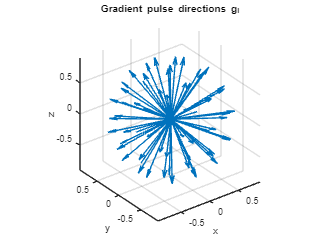

S =     45
    46
    47
    48
    49
    50
    71
    72
    73
    74



figure
quiver3(0*g(:,1), 0*g(:,1), 0*g(:,1), g(:,1), g(:,2), g(:,3))
axis vis3d
xlabel x, ylabel y, zlabel z
title('Gradient pulse directions g_i')